# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 05-Sep-2020 19:43:32

## Setup the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 19);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Vendor", "PickupTime", "DropoffTime", "Passengers", "Distance", "PickupLon", "PickupLat", "RateCode", "HeldFlag", "DropoffLon", "DropoffLat", "Paytype", "Fare", "ExtraCharge", "Tax", "Tip", "Tolls", "ImpSurcharge", "TotalCharge"];
opts.VariableTypes = ["categorical", "datetime", "datetime", "double", "double", "double", "double", "categorical", "categorical", "double", "double", "categorical", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Vendor", "RateCode", "HeldFlag", "Paytype"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "PickupTime", "InputFormat", "yyyy-MM-dd HH:mm:ss");
opts = setvaropts(opts, "DropoffTime", "InputFormat", "yyyy-MM-dd HH:mm:ss");

% Import the data
data = readtable("F:\Predictive Modelling and Machine Learning\Taxi Data\Taxi Data\yellow_tripdata_2015-01.csv", opts)

data = 254980×19 table
    Vendor        PickupTime             DropoffTime        Passengers    Distance    PickupLon    PickupLat    RateCode    HeldFlag    DropoffLon    DropoffLat    Paytype    Fare    ExtraCharge    Tax    Tip     Tolls    ImpSurcharge    TotalCharge
    ______    ___________________    ___________________    __________    ________    _________    _________    ________    ________    __________    __________    _______    ____    


data.RateCode = renamecats(data.RateCode,'1','Standard');
data.RateCode = renamecats(data.RateCode,'2','JFK');
data.RateCode = renamecats(data.RateCode,'3','Nassau or Westchester');
data.RateCode = renamecats(data.RateCode,'Nassau or Westchester','Newark');
data.RateCode = renamecats(data.RateCode,'4','Nassau or Westchester');
data.RateCode = renamecats(data.RateCode,'5','Negotiated');
data.RateCode = renamecats(data.RateCode,'6','Group Ride');
data.Vendor = renamecats(data.Vendor,'1','Creative Mobile Technologies');
data.Vendor = renamecats(data.Vendor,'2','Verifone Inc.');
data.Paytype = renamecats(data.Paytype,'1','Credit Card');
data.Paytype = renamecats(data.Paytype,'2','Cash');
data.Paytype = renamecats(data.Paytype,'3','No charge');
data.Paytype = renamecats(data.Paytype,'4','Voided Trip')

data = 254980×19 table
               Vendor                   PickupTime             DropoffTime        Passengers    Distance    PickupLon    PickupLat    RateCode    HeldFlag    DropoffLon    DropoffLat      Paytype      Fare    ExtraCharge    Tax    Tip     Tolls    ImpSurcharge    TotalCharge
    ____________________________    ___________________    ___________________    __________    ________    _________    _________    ________    ________    __________    __________    

## Initial Visualizations

### Distance as a funtion of fare and Rate type

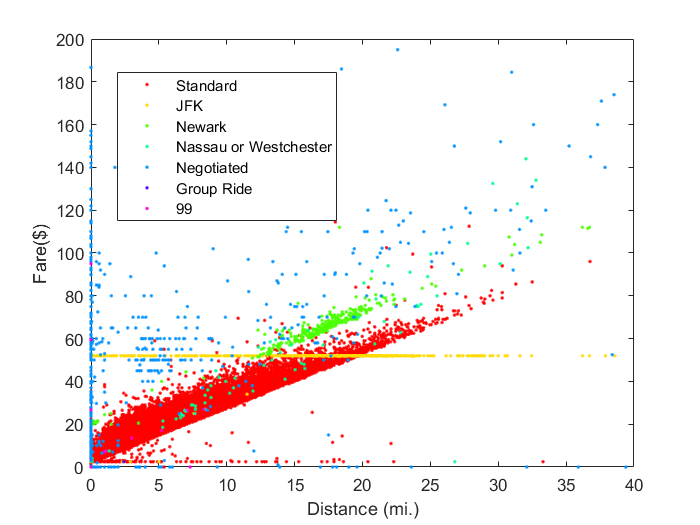


gscatter(data.Distance, data.Fare, data.RateCode)
xlabel('Distance (mi.)')
ylabel('Fare($)')
xlim([0 40])
ylim([0 200])

## Trip Distance

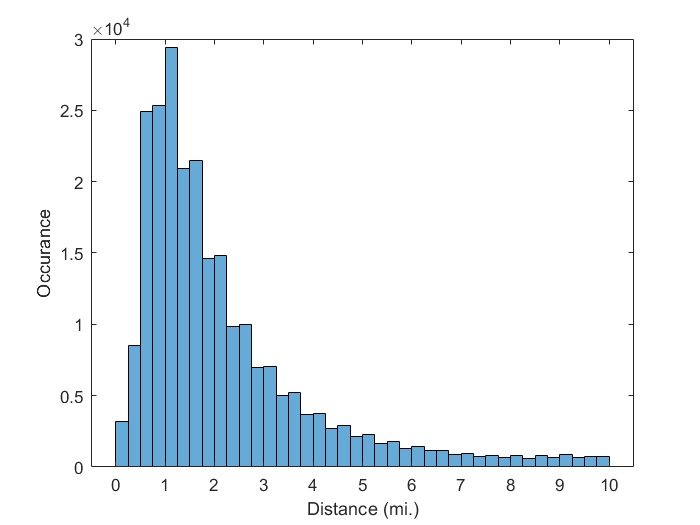

distancebins=0:0.25:10;
histogram(data.Distance, distancebins)
xlabel('Distance (mi.)')
ylabel('Occurance')

## Fares

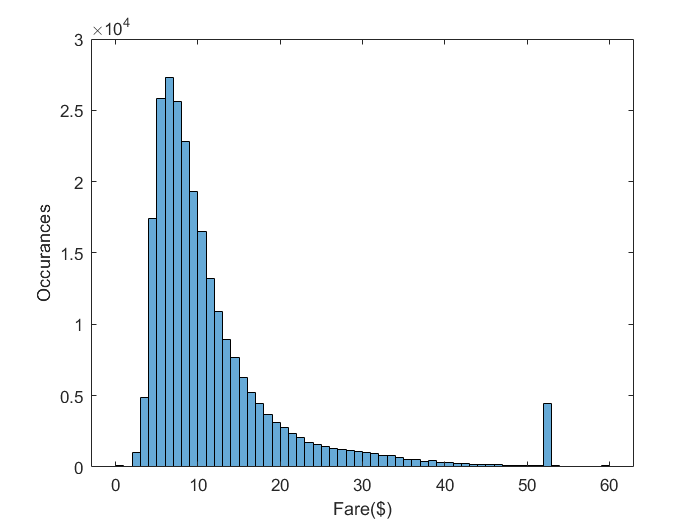

farebin=0:1:60;
histogram(data.Fare,farebin)
xlabel('Fare($)')
ylabel('Occurances')

## Fares and tips relation

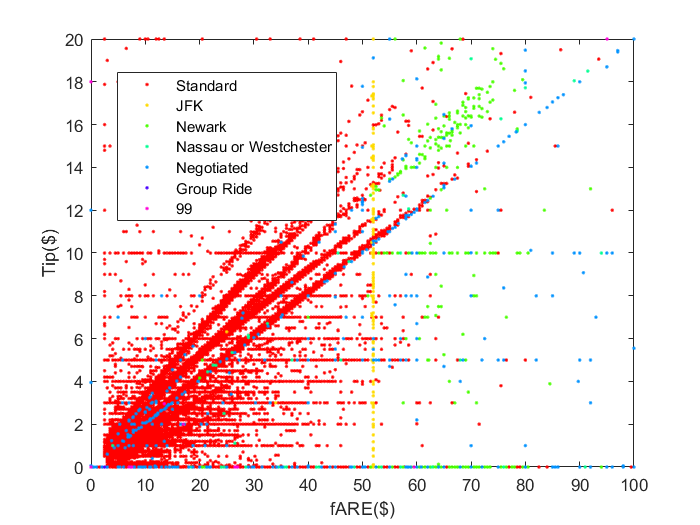

gscatter(data.Fare,data.Tip, data.RateCode)
xlabel('fARE($)')
ylabel('Tip($)')
xlim([0 100])
ylim([0 20])

## Locations

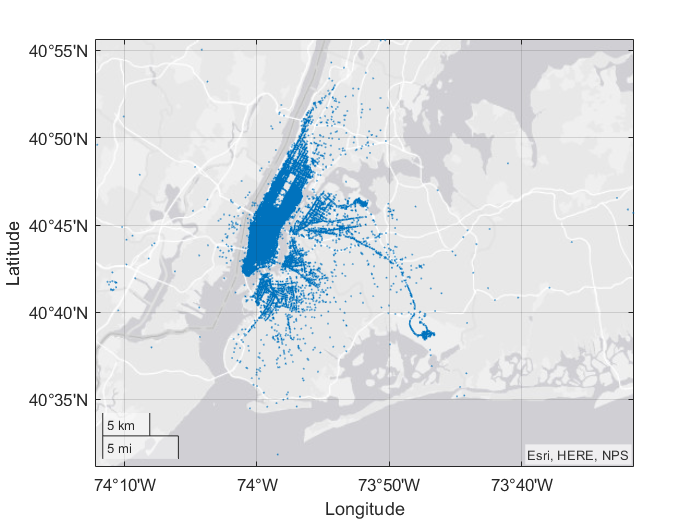

geoscatter(data.PickupLat, data.PickupLon, '.', 'SizeData',1)

geolimits([40.519 40.927],[-74.204 -73.525])

## Clear temporary variables

clear opts